# Project #2

## PECE Method

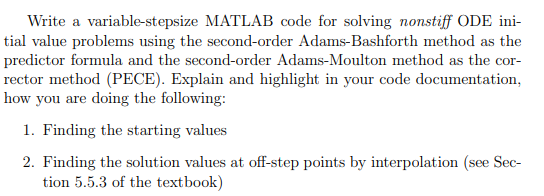

Following is the code for my PECE_MethodOrder2.m function, which implements the procudes decscribed above. In each problem of the project, we call this function to perfom the computations. 

function [t_out, y_out, h_out, f_out] = PECE_MethodOrder2(f, y_initial, end_time, error_tolerance)
%thetaMethod Solves an ODE via the 2nd order PECE method, with variable 
%   time steps.
%
%   expectations:
%   f   @(t, y)function 
%       y   Nx1 double
%       t   double

% Initialize variables
start_time = 0;
t_out = [start_time];    % These are the output data. We will graph
y_out = [y_initial]; %     y1_out and y2_out versus t_out.
f_out = [f(start_time, y_initial)];
h_out = [0];
AB_C3 = 5/12; % Coefficients for Adams-Bashforth and Adams-Moulton methods
AM_C3 = -1/12;%     respectively, taken from tables 5.1 and 5.2 in the text.
C = AM_C3/(AM_C3-AB_C3);


Here is where we find the starting values, as called for in number 1 of the prompt:


% Compute 2nd values
h = .0001; % We need another "intial" value to get PECE going
%FEM with tiny h
    new_time = t_out(end) + h; 
    new_y = y_out(:,end) + h*f_out(:,end);
    new_f = f(new_time, new_y); 
    t_out = [t_out, new_time]; % append to outputs
    y_out = [y_out, new_y]; 
    f_out = [f_out, new_f];
    h_out = [h_out, h];
%end FEM
    
% Compute remaining values
while t_out(end) < end_time %n matches the column index of output which was last filled.
    new_time = t_out(end) + h; %increment time
    new_y_p = y_out(:,end) + (h/2)*(3*f_out(:,end)-f_out(:,end-1)); %Predict via AB
    new_f = f(new_time, new_y_p); %Evaluate f
    new_y = y_out(:,end) + (h/2)*f_out(:,end) + (h/2)*new_f; %Correct via AM
    new_f = f(new_time, new_y); %Evaluate f
    error_estimate = C*norm(new_y - new_y_p);
    if false %error_estimate > error_tolerance 
        error_estimate
    end
    if error_estimate < error_tolerance 
        t_out = [t_out, new_time]; %append to outputs
        y_out = [y_out, new_y]; 
        f_out = [f_out, new_f];
        h_out = [h_out, h];
    end 
    h = computeTimestep(h, error_estimate, error_tolerance); 
end
h;
end


Note here is where we define the function which computes the stepsize. Its comments explain how it works. 


%% Function definitions
function output = computeTimestep(h, error_estimate, error_tolerance)
%computeTimestep Computes the size of the next timestep for PECE.
%   This function returns 
%        h*(tolerance_margin*error_tolerance/error_estimate)^(1/3). 
%
%   We want to choose h so that our error estimate is within our error
%   tolerance, but close to it (say, 90%). Thus we set 
%                       tolerance_margin = 0.9
%   We take the cube root because this is a 2nd order method which means
%   the error is of order h^3, thus our r-value is going to get cubed. 

tolerance_margin = 0.9; %default 0.9

r = (tolerance_margin*error_tolerance/error_estimate)^(1/3);

output=r*h;
end

Now we can examine the code for the function offStepPoint.m, which finds the solution values at off-step points by interpolation. It does this after PECE_MethodOrder2.m has been run, so it can use the data that has been generated already without having to recompute any previous values of f or y. 

function output = offStepPoint(t_star,t,y,h,f)
%offStepPoint Interpolates to find y(t) for any valid t, given the data
%output from PECE_MethodOrder2(). 
%   Expectations: 
%   t = double, with t_list(1)<t<t_list(end). This is the point at which we
%       are evaluating.

n=find(t<=t_star); %find indeces of t_list for elements <= t
n=n(end); %only keep the largest such index
n=n+1; %in the theory we're used to thinking of y(n) as the value we're 
        %about to compute, and y(n-k) as past values, so now the last
        %computed value is y(n-1). 
if t_star==t(n-1) %check to see if we're done already
    output = y(:,n-1);
    return
end
h_star = t_star-t(n-1);
% This formula is obtained by approximating f at t(n-1) and t(n-2) by the
% interpolating polynomial, and integrating both sides from t(n-1) to
% t_star. Below we simply plug in to the formula obtained on paper. 
y_star = y(:,n-1)+h_star*f(:,n-2)+((f(:,n-2)-f(:,n-1))/(2*h(n-1)))*h_star^2;
output=y_star;
end


This is where Project2.m begins, now that we have examined the functions which we will use. 

% Options
plot_on = true; %I can toggle this to speed things up while debugging

## Problem 1 - Easy Problem

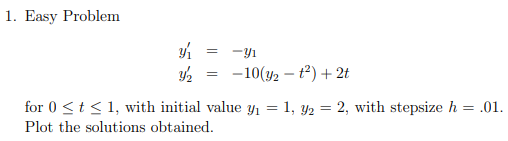

% The given data
f = @(t,y)[-y(1);-10*(y(2)-t^2)+2*t];
end_time = 1;
y_initial = [1;2];

[t,y,h_list,f_list] = PECE_MethodOrder2(f, y_initial, end_time, 1e-6);

offStepPoint(1, t, y, h_list, f_list)

if plot_on    
    myPlot2(t, y(1,:), y(2,:), 'Problem 1 PECE', 'y1', 'y2');
    exportgraphics(gcf, 'prob1_y1_and_y2_vs_t.png')
    myPlot1(t, h_list, 'Problem 1 PECE', 'h');     
    exportgraphics(gcf, 'prob1_h.png')
end

Here is the output for error tolerance $10^{-3}$:

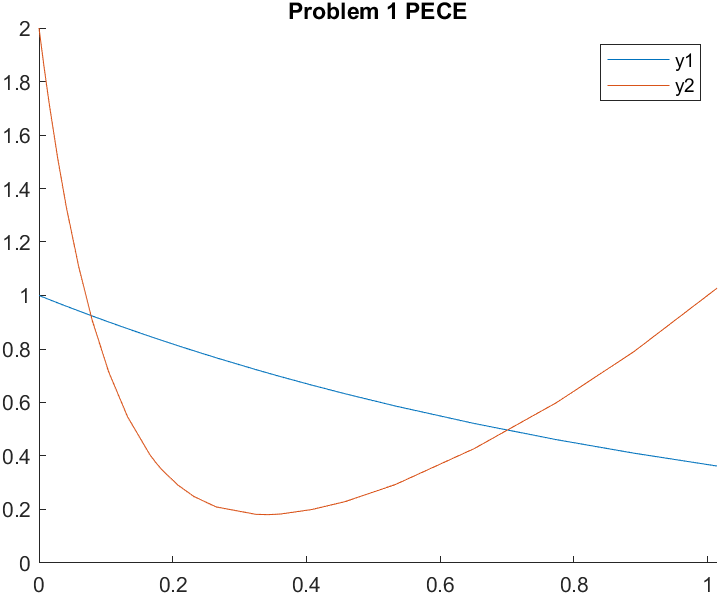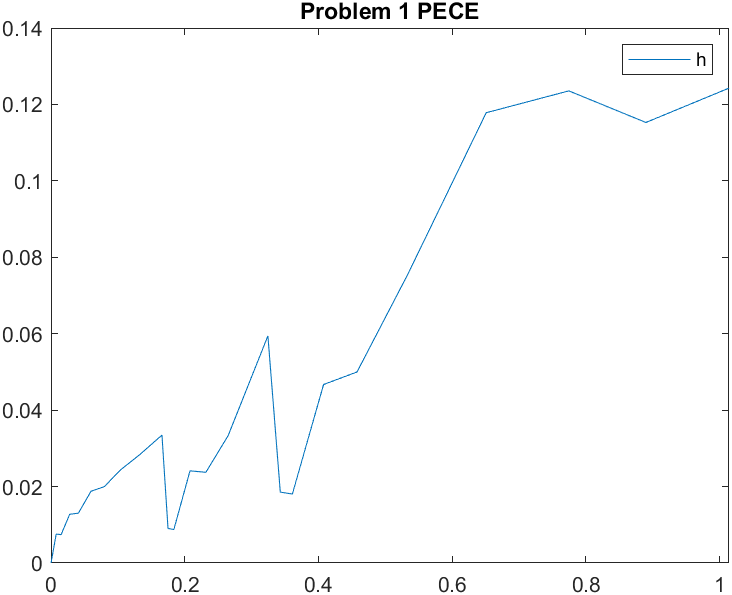

and this is with $ETOL=10^{-6}$:

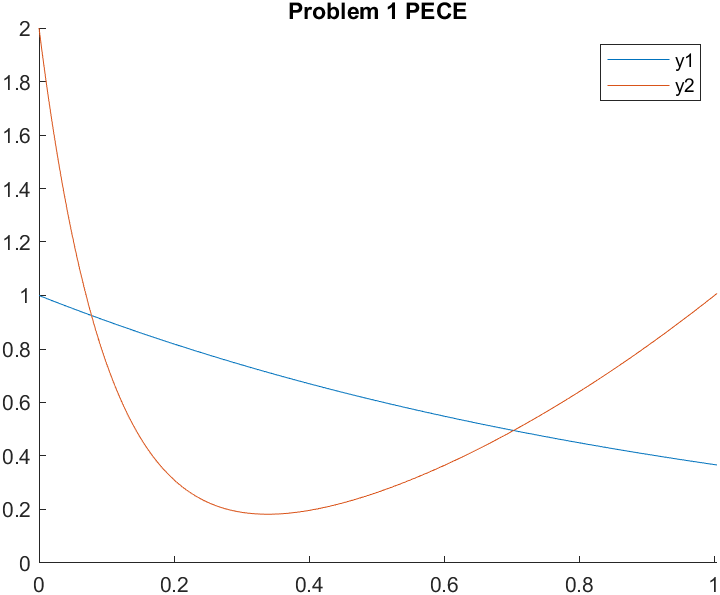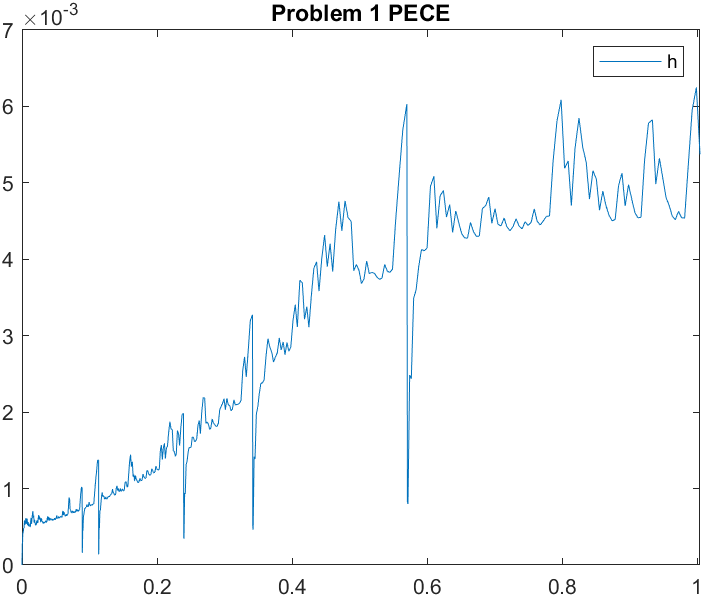

Neither of these results is a surprise, we can see by inspection that $y1$ should be exactly $e^{-x}$ and $y2$ is of the form of our classic stiffness problem, but its coefficient isn't large enough to mess with this code (which was intended for use with nonstiff problems), so we see a meandering "transient", settling in to follow $y2=x^2$. 

## Problem 2 - Predator-Prey Problem

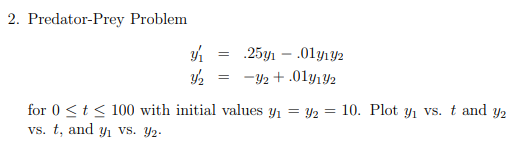

% The given data
f = @(t,y)[.25*y(1)-.01*y(1)*y(2); -y(2)+.01*y(1)*y(2)];
%Jf = @(y1,y2)[.25 - .01*y2, -.01*y1; .01*y2, .01*y1 - 1];
end_time = 100;
y_initial = [10;10];

[t,y,h_list,f_list] = PECE_MethodOrder2(f, y_initial, end_time, 1e-6);

offStepPoint(1, t, y, h_list, f_list)

if plot_on    
    myPlot2(t, y(1,:), y(2,:), 'Problem 2 PECE', 'y1', 'y2')
    xlabel('t')
    exportgraphics(gcf, 'prob2_y1_and_y2_vs_t.png')
    figure
        plot(y(1,:),y(2,:)) %y2 vs y1
        title('Problem 2 PECE')
        xlabel('y1')
        ylabel('y2')   
        exportgraphics(gcf, 'prob2_y1_vs_y2.png')
    myPlot1(t, h_list, 'Problem 2 PECE stepsizes', 'h');     
    exportgraphics(gcf, 'prob3_h.png')
end

Here is the output for error tolerance $10^{-3}$:

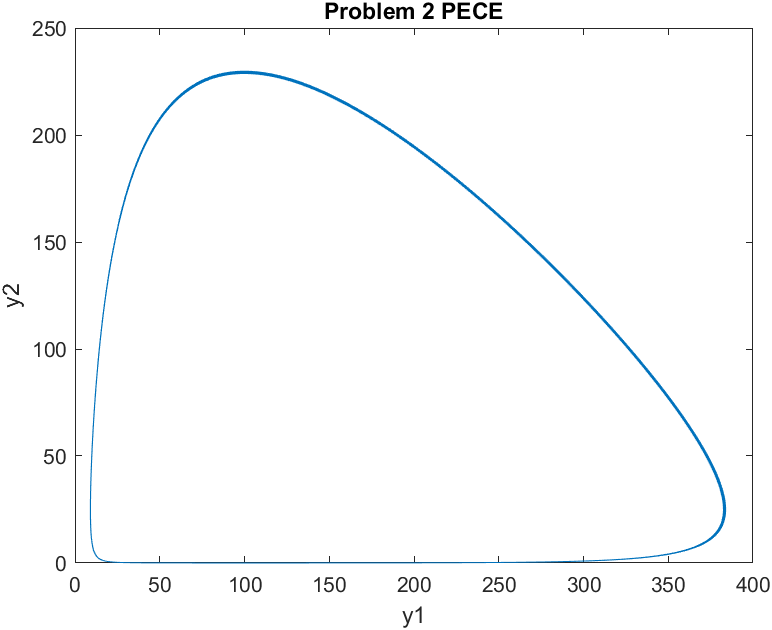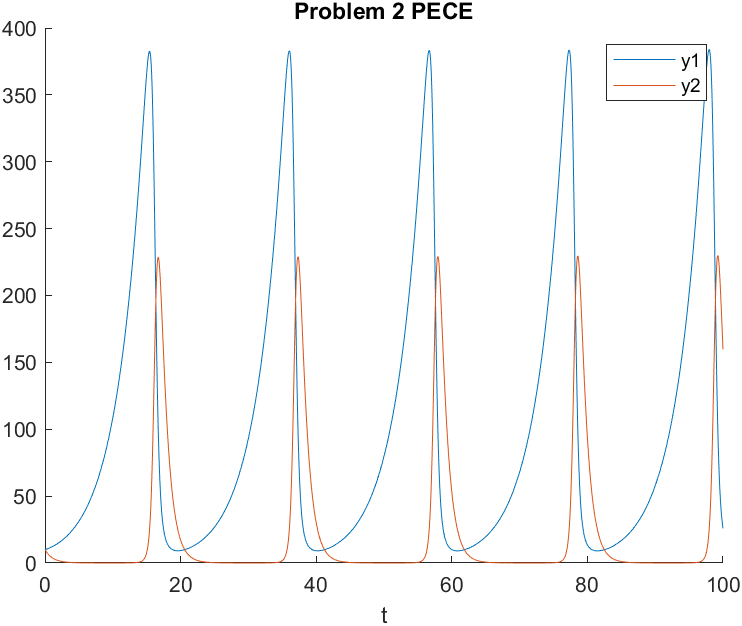

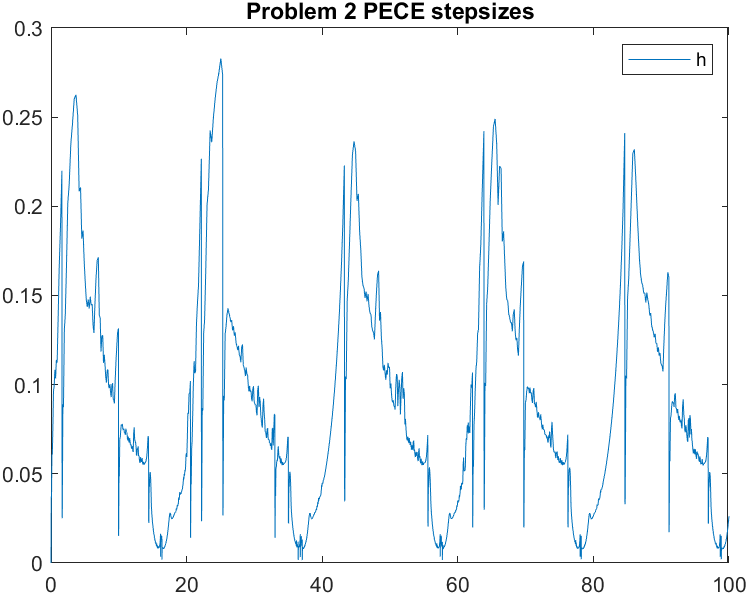

And this and this is with $ETOL=10^{-6}$. Let's take an up-close look this time:

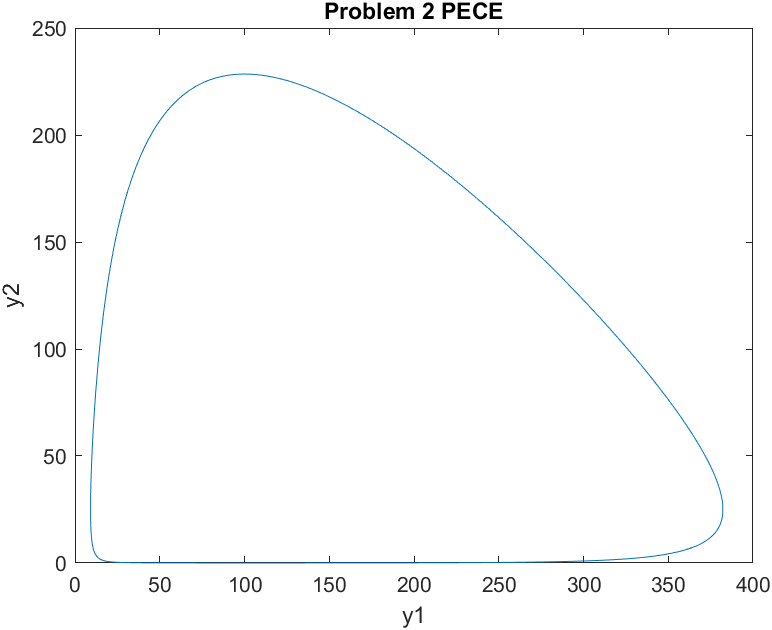

We're getting what looks like very accurate results here since we've plotted five periods and the plot looks like a single loop, so we're seeing a vanishingly small amount of drift. 

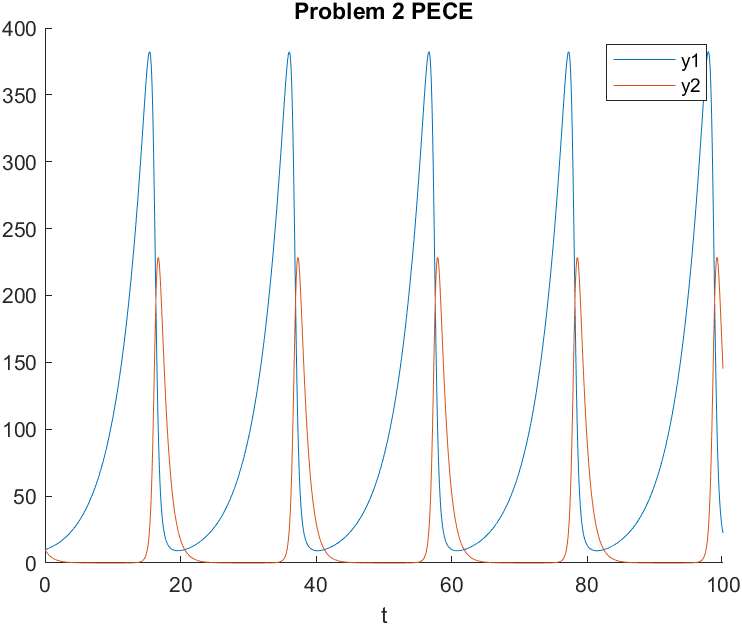

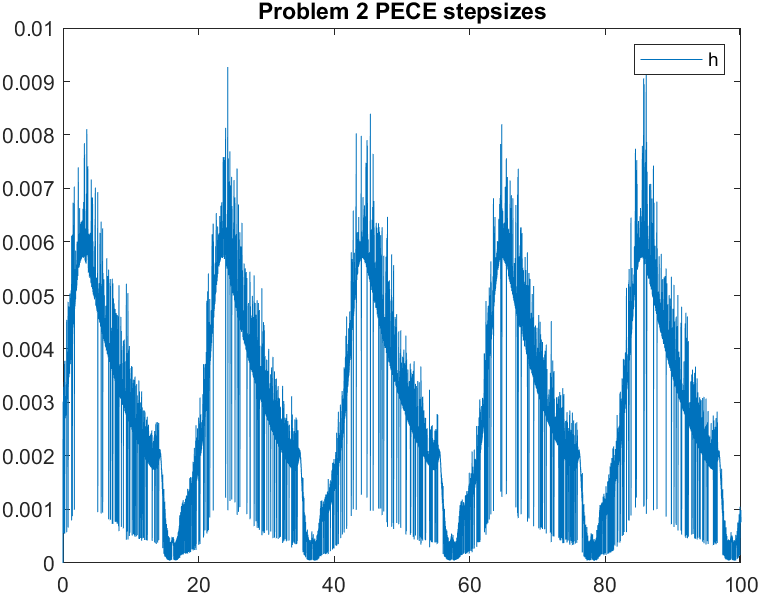

When we see these two plots stacked on top of each other so their horizontal axes are aligned, we can see that the stepsize gets large when the derivatives of $y1$ and $y2$ are small, and vice-versa. This tells us that our stepsize selection algorithm is working the way we want it to. 

## Problem 3 - Van der Pol's Equation

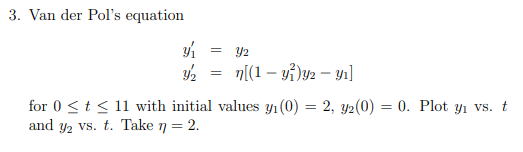

% The given data
eta = 2
f = @(t,y)[y(2);eta*((1-y(1)^2)*y(2)-y(1))];
end_time = 11;
y_initial = [2;0];

[t,y,h_list,f_list] = PECE_MethodOrder2(f, y_initial, end_time, 1e-6);

offStepPoint(1, t, y, h_list, f_list)

if plot_on    
    myPlot2(t, y(1,:), y(2,:), 'Problem 3 PECE', 'y1', 'y2')
    xlabel('t')
    exportgraphics(gcf, 'prob3_y1_and_y2_vs_t.png')
    figure
        plot(y(1,:),y(2,:)) %y2 vs y1
        title('Problem 3 PECE')
        xlabel('y1')
        ylabel('y2')   
        exportgraphics(gcf, 'prob3_y1_vs_y2.png')
    myPlot1(t, h_list, 'Problem 3 PECE stepsizes', 'h');     
    exportgraphics(gcf, 'prob3_h.png')
end

Here is the output for error tolerance $10^{-3}$:

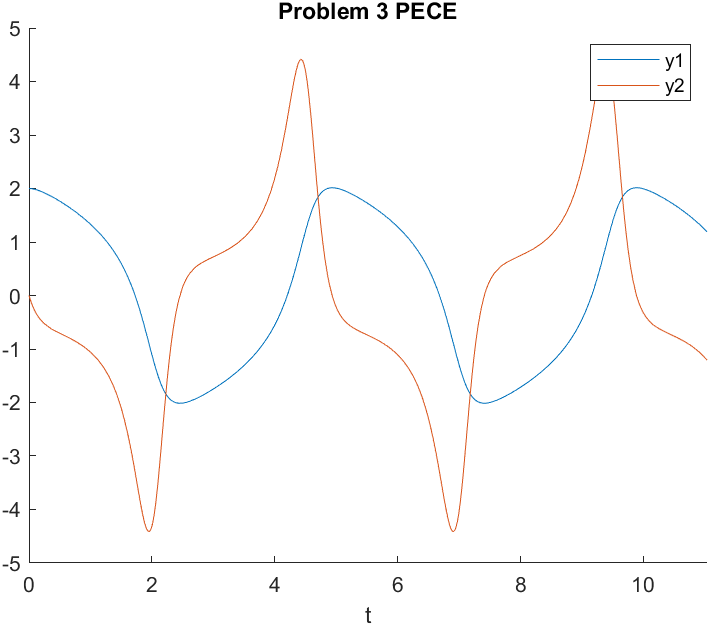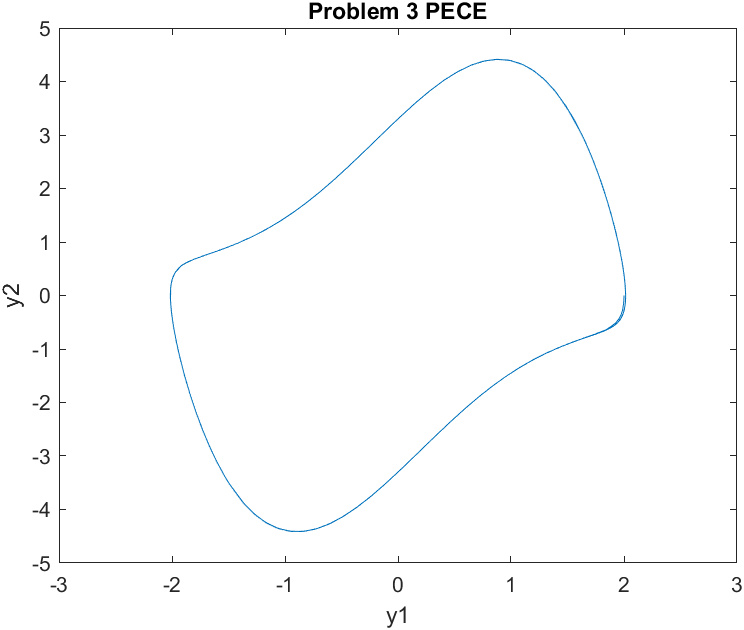

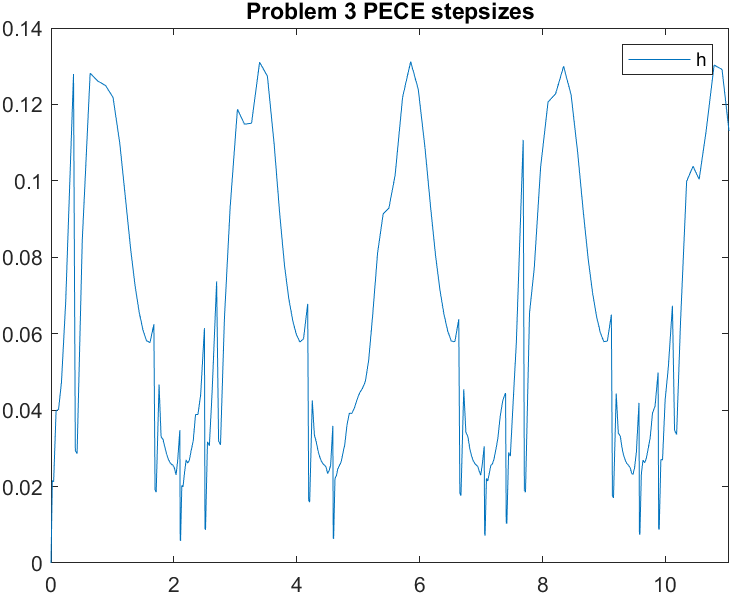

And this and this is with $ETOL=10^{-6}$. 

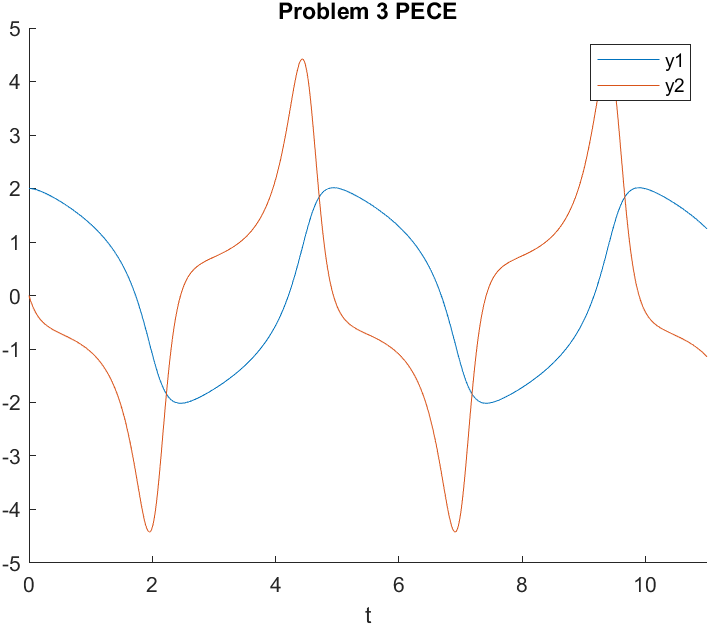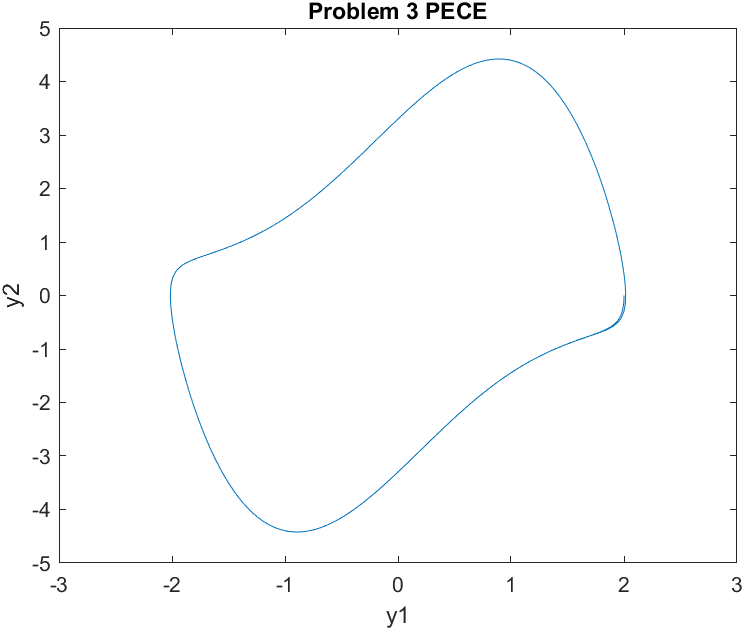

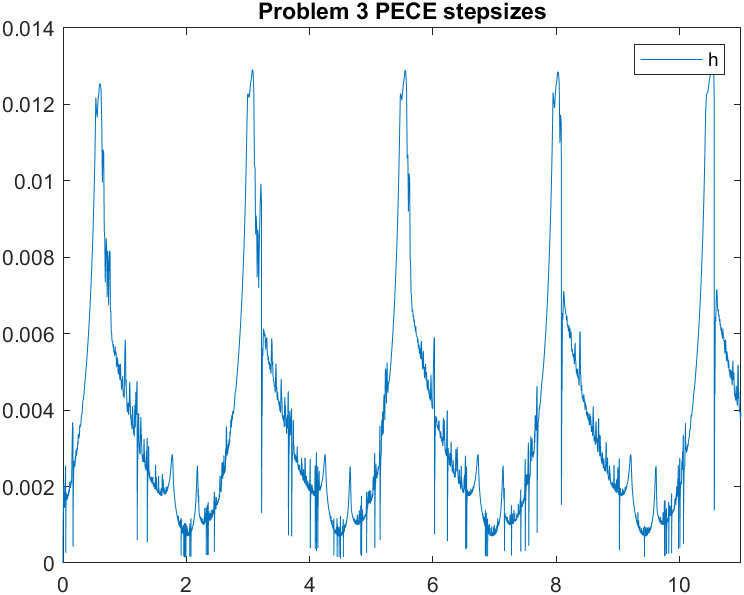

In both cases our figures are qualitatively the same, and the only real difference is in the care we have taken to keep a low error, whose effect would show up in scientific application. Again as in problem 2, we see the step size is inversely related to the magnitude of the derivatives of y1 and y2.     

## Problem 4 - Advection PDE via MOL

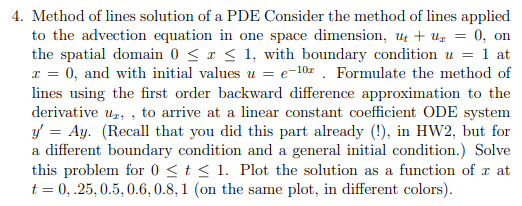

Our guiding PDE for this problem is 

                                                    
$$u_t+u_x=0,$$


which we rewrite as 

                                                            
$$u_t = -u_x.$$


This is the system we want to discretize, splitting up $u(t, x)$ as a bunch of functions $u_i(t) := u(t, x_i)$where $x_i$ are a bunch of evenly spaced points, spread $\Delta x$ apart from each other. Now using the first order backwards difference approximation, we can approximate $u_x(t,x_i)$ with $t$ variable and $x_i$ fixed as 

                                                            
$$u_x \approx \frac{u_{i}-u_{i-1}}{\Delta x}$$


except of course at $x_0$, since our boundary condition has $u(t,0)$ fixed for all time, which means $u_0=0$. Thus when we restrict to our discretized lines, we see that $u_t=u_i'$, and we obtain


$$u_i'=-u_x\approx \frac{u_{i-1}-u_{i}}{\Delta x}$$


which we can write in matrix form as 

                                                            ${\vec u}'=A \vec u$, 

where 

                                             
$$A = \left[\begin{array}{ccccc}
0 & 0 & 0 & \dots & 0\\ 
1 & -1 & 0 & \dots & 0\\  
0 & 1 & -1 & \dots & 0 \\
\vdots & \vdots & \ddots & \ddots & 0 \\
0 & 0 & \dots & 1 & -1
\end{array}\right]$$


Then at this point we can simply pass this system of ODEs to PECE_MethodOrder2.m, and observe the output. 

% Knobs I can turn
partition_count=100;

% Using MOL on the given data to construct an ODE
spatial_domain = [0,1];
delta_x=(spatial_domain(2)-spatial_domain(1))/partition_count;
%Note that u_t + u_x = 0 for this problem, so u_t = -u_x, which we will
%approximate. 

%Now we construct the coefficient matrix using the first order backward
%difference approximation to the derivative u_x.
A = zeros(partition_count);
    % start at i=2 since u_0=1 always, so u_0'=0
    for i = 2:partition_count %u_i' = u_{i-1}-u_i, over delta_x (done later)
        A(i, i-1) = 1;
        A(i, i) = -1;
    end
f = @(t, y)[(1/delta_x)*A*y]; % here we divide by delta_x
end_time = 1;
x = linspace(spatial_domain(1), spatial_domain(2), partition_count)'; 
y_initial = exp(-10*x);

times = [0,0.25,0.5,0.6,0.8,1]; %times at which we want to find u(x,t) for 
                                %each t in the list
                                
[t,y,h_list,f_list] = PECE_MethodOrder2(f, y_initial, end_time, 1e-6);

y_offStepPoints = zeros(partition_count, length(times));
for i=1:length(times)
    y_offStepPoints(:,i) = offStepPoint(times(i), t, y, h_list, f_list);
end

%plot u vs t with lines ranging across x
figure
hold on % plot on the same figure
cc=parula(partition_count);
for i=1:partition_count
    plot(t, y(i,:), 'color', cc(i,:))
end
c = colorbar('Direction','reverse');
c.Label.String = "color denotes x coordinate";
hold off
xlim([0 t(end)]) % stop a weird space from appearing on the right side of the plot
title(strcat('Problem 4 MOL'))
xlabel('t, time')
ylabel('u, temperature')
exportgraphics(gcf, 'prob4_u_vs_t.png')
%legend({strcat(varname1), strcat(varname2)})     

%plot u vs x with lines ranging across t
figure
hold on % plot on the same figure
cc=copper(length(times));
for i=1:length(times)
    plot(x, y_offStepPoints(:,i), 'color', cc(i,:))
end
hold off
xlim([0 times(end)]) % stop a weird space from appearing on the right side of the plot
title(strcat('Problem 4 MOL, Offstep Points'))
xlabel('x')
ylabel('u')
legend({strcat("t=", string(times(1))), strcat("t=", string(times(2))), ...
    strcat("t=", string(times(3))), strcat("t=", string(times(4))), ...
    strcat("t=", string(times(5))), strcat("t=", string(times(6))), })
exportgraphics(gcf, 'prob4_u_vs_x.png')

%plot h
myPlot1(t, h_list, 'Problem 4 MOL stepsizes', 'h');   
xlabel('t')
ylabel('h')
exportgraphics(gcf, 'prob4_h.png')

Before we show all the plots, observe here the code used to interpolate the off-step points, the comments do a good job of explaining what is going on: 

function output = offStepPoint(t_star,t,y,h,f)
%offStepPoint Interpolates to find y(t) for any valid t, given the data
%output from PECE_MethodOrder2(). 
%   Expectations: 
%   t = double, with t_list(1)<t<t_list(end). This is the point at which we
%       are evaluating.

n=find(t<=t_star); %find indeces of t_list for elements <= t
n=n(end); %only keep the largest such index
n=n+1; %in the theory we're used to thinking of y(n) as the value we're 
        %about to compute, and y(n-k) as past values, so now the last
        %computed value is y(n-1). 
if t_star==t(n-1) %check to see if we're done already
    output = y(:,n-1);
    return
end
h_star = t_star-t(n-1);
% This formula is obtained by approximating f at t(n-1) and t(n-2) by the
% interpolating polynomial, and integrating both sides from t(n-1) to
% t_star. Below we simply plug in to the formula obtained on paper. 
y_star = y(:,n-1)+h_star*f(:,n-2)+((f(:,n-2)-f(:,n-1))/(2*h(n-1)))*h_star^2;
output=y_star;
end

Now observe the plots with $ETOL = 10^{3}$:

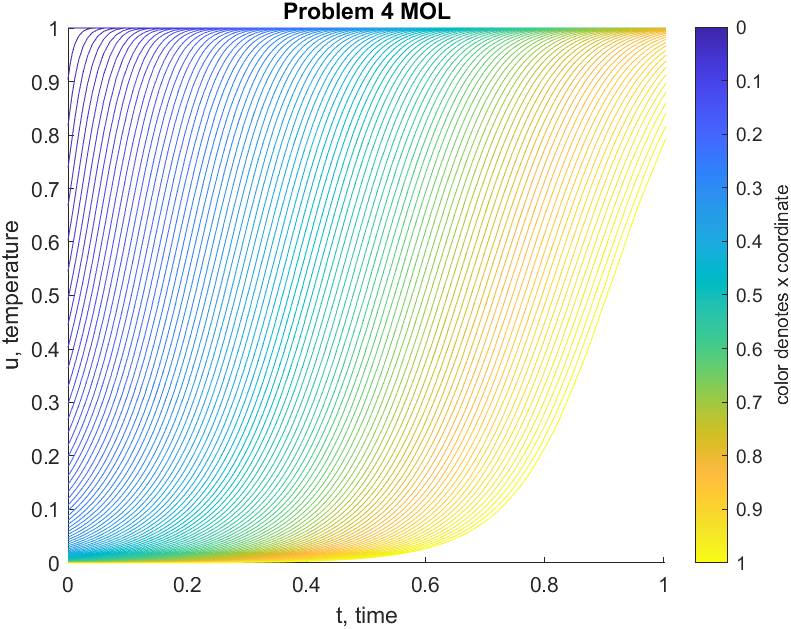

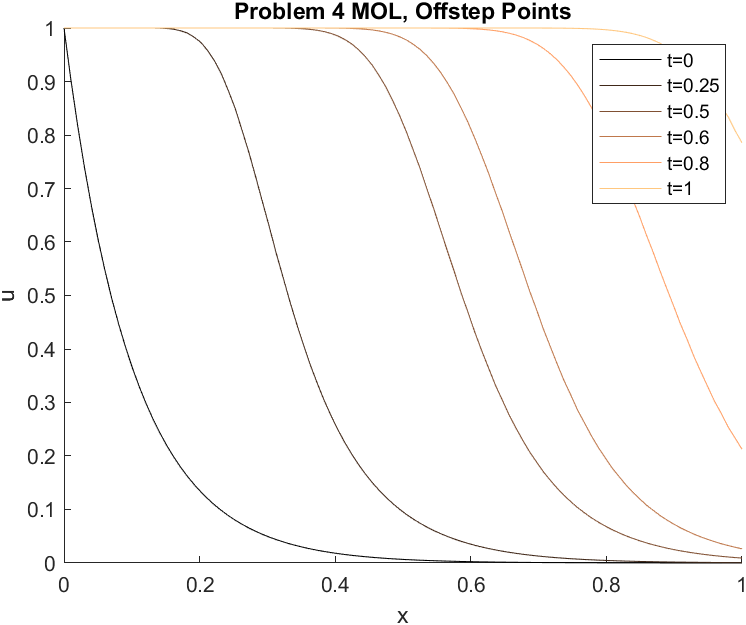

These beautiful graphics demonstrate exactly what we'd expect in e.g. a heat transfer scenario. In the first plot we can see that only the very blue lines are warm, and the rest of the bar is cold, that is, all the way down at the bottom of the plot. Then as we move forward in time (that is, to the right),  we see each line (each point) follows a logistic curve up to the top. This agrees with the physical idea that the rate of heat transfer is proportional to the temperature difference. In the second plot, one whole curve represents a "snapshot" of the whole bar at a given point in time. At time zero, the leftmost points are warm, but the rest is cold. Then in successive curves we see the bar warming up from left to right, eventually become warm almost everywhere. 

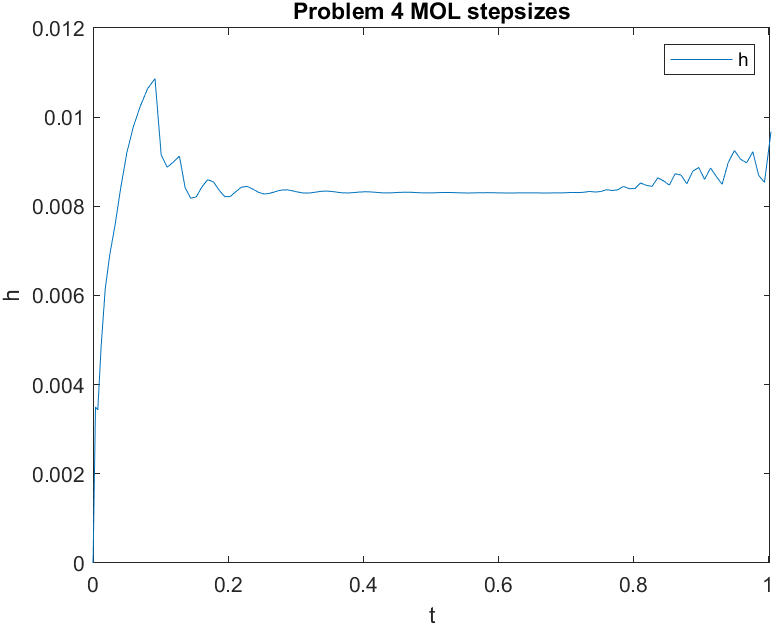

And here are the same plots with the error tolerance all the way down at $ETOL=10^{-6}$: